# Interpolation, direct method

clear all
close all
% nodes
X = [1, 2, 3, 4, 5, 6]';
Y = [2, 6, 3, 8, 1, 9]';
m =  length(X);
% coeff matrix
A = ones(m ,m);
A(:, 1) = X.^5;
A(:, 2) = X.^4;
A(:, 3) = X.^3;
A(:, 4) = X.^2;
A(:, 5) = X;
A;
b = Y;
% solving the system Ax = b-type sol = A/b
sol = A\b

sol =     0.6833
  -11.7083
   75.1667
 -223.2917
  302.1500
 -141.0000


plot(X, Y, 'ro');
%symbolic way
syms t
P = sol(1)*t^5 + sol(2)*t^4 + sol(3)*t^3 + sol(4)*t^2 +sol(5)*t + sol(6)

$$P = \frac{769364936342425\,t^{5}}{1125899906842624}-\frac{3295602852320445\,t^{4}}{281474976710656}+\frac{5289383937354163\,t^{3}}{70368744177664}-\frac{7856377084335079\,t^{2}}{35184372088832}+\frac{1328869753330013\,t}{4398046511104}-\frac{4960996464525089}{35184372088832}$$

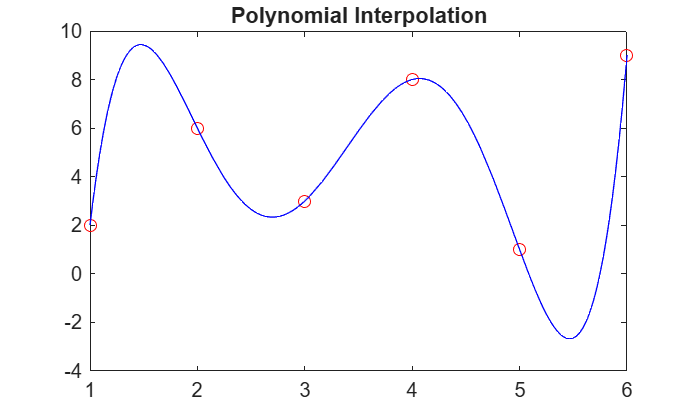

$$ans = \frac{17\,x^{7}}{360}-\frac{133\,x^{6}}{90}+\frac{6821\,x^{5}}{360}-\frac{9227\,x^{4}}{72}+\frac{22021\,x^{3}}{45}-\frac{375073\,x^{2}}{360}+\frac{22523\,x}{20}-461$$

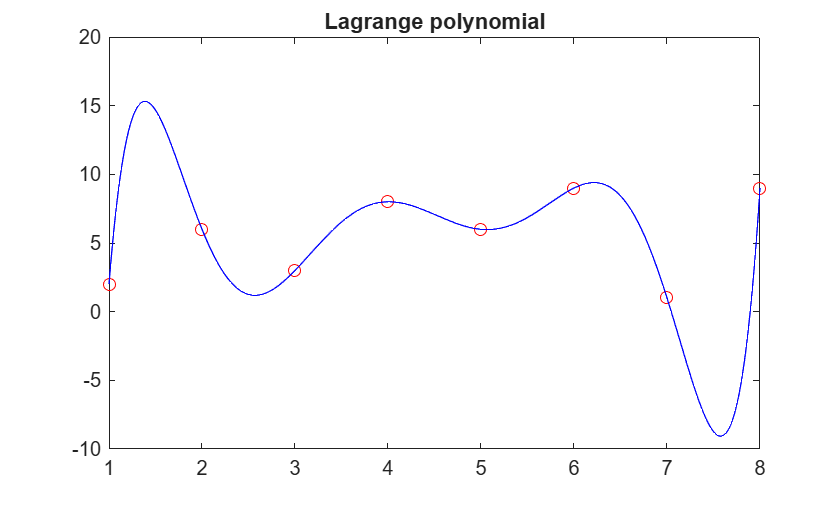

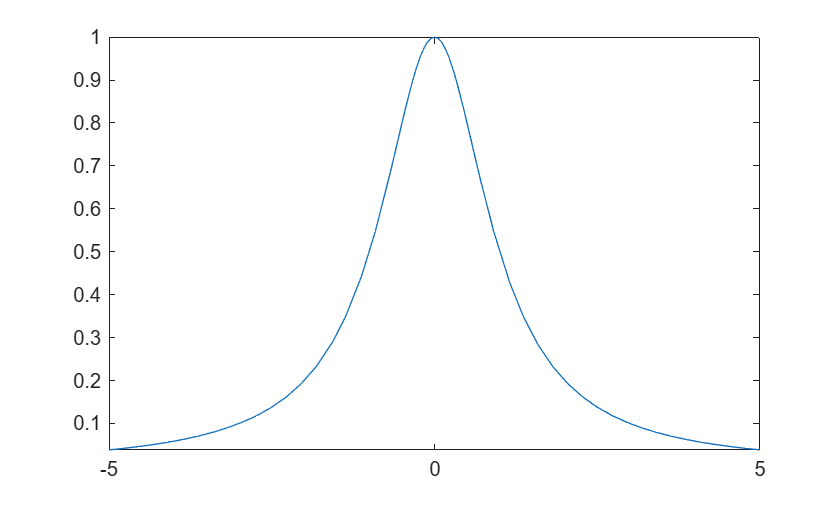

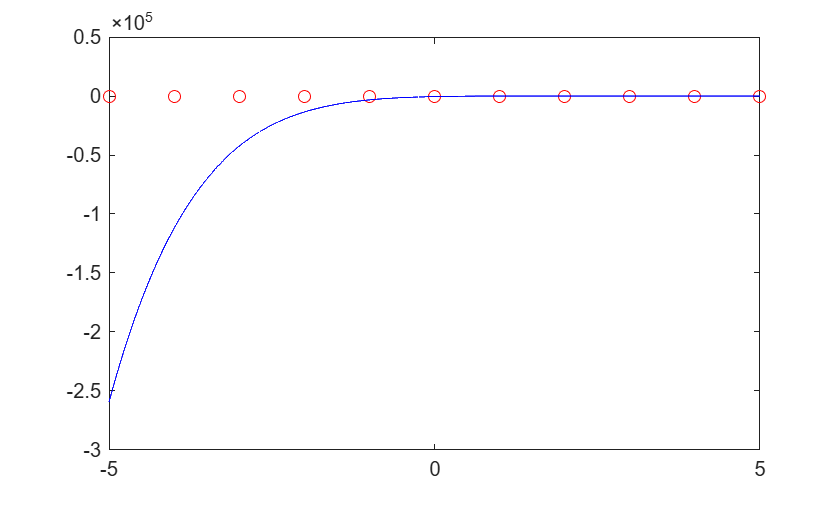

hold on
fplot(P, [min(X), max(X)], 'b')
title('Polynomial Interpolation')